% done first with /media/sil1/Pogona Vitticeps/Nitzan_behavioral_data/PV134/PV134_trial11_OG_singles_2023_04_03/Record Node 101
rec = OERecording('/media/sil1/Pogona Vitticeps/PV149/Not_Orgenised/PV149_Trial89_singles_635/Record Node 101');


Extracting meta data from: /media/sil1/Pogona Vitticeps/PV149/Not_Orgenised/PV149_Trial89_singles_635/Record Node 101/...
Extracting time stamp information...
Checking integrity of all records in ch1...
saving meta data
No .chMap files were found for this recording
No layout file in directory, to add layout please add a *.chMap file to the data directory with the layout name


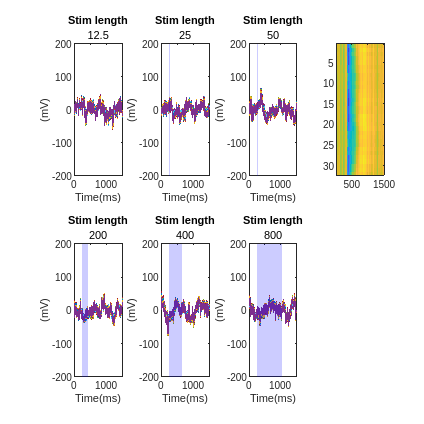


%% generate the segments  for each stimuli - 250 ms before the start, 1250
% ms after . 

% get the triggers times
trig = rec.getTrigger();


% camera triggers are 7-8, stim are 15-16 (in this particular setting)

stim_up = cell2mat(trig(15)); % up times from the begining of rec in ms.
stim_down = cell2mat(trig(16));
stim_len = stim_down - stim_up;
% get the data for each trigger point:
t_trig_ms = 250;
[segs,times]= rec.getData(1:32,stim_up-t_trig_ms,1500); 

% save mat for the segments?
%create full dir name
full_segs_dir = fullfile(rec.recordingDir, 'stimulations_segments.mat');
save(full_segs_dir, "segs",'-v7.3'); % have to be saved in v7.3 because the file is very big.


% plot the raw data.
mean_stim = squeeze(mean(segs,2));
imagesc(times, (1:32),mean_stim);

## create a analysis file for plots

AnalysisFolder = strcat(rec.recordingDir, 'Analysis');
status = mkdir(AnalysisFolder);


## average for all channels:

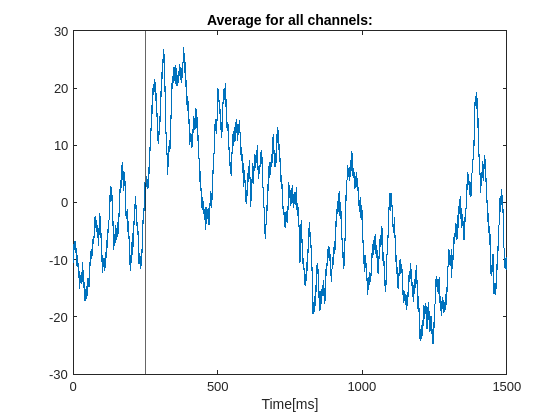

mean_all = mean(mean_stim,1);
plot(times,mean_all);
xline(t_trig_ms);
title('Average for all channels:')
xlabel('Time[ms]')

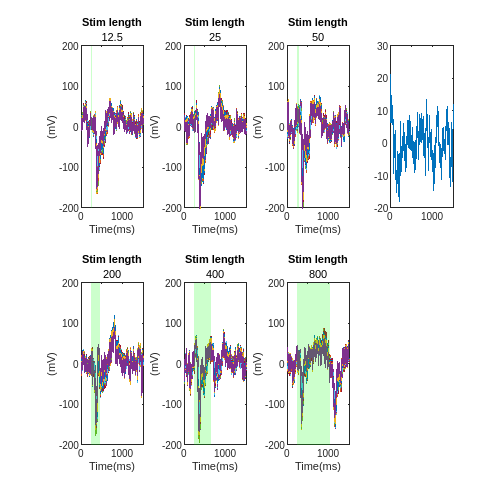

% plot ch1:
plot(times,mean_stim(1,:))

## plot all ch using subplots:

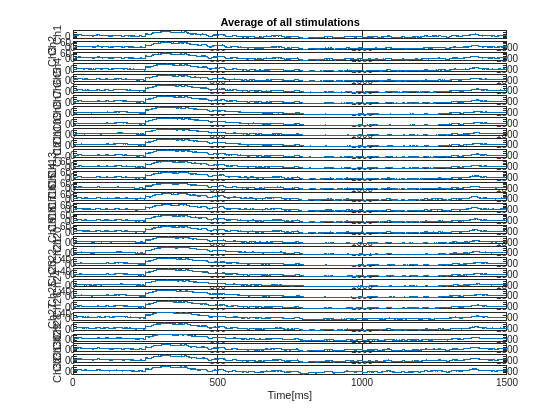

% using subplots:
for i = 1:32
   subplot(32,1,i);
   plot(times,mean_stim(i,:));
   ylabel(['Ch',num2str(i)]);
   if i ==1
       title('Average of all stimulations')
   end
end
xlabel('Time[ms]')

## plot all Ch

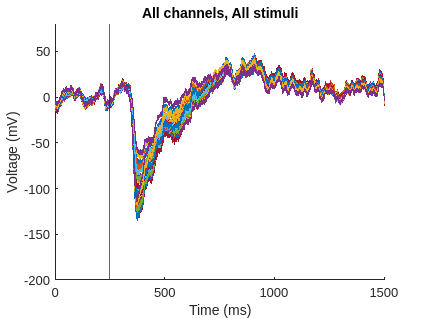

figure 
title('All channels, All stimuli')
hold on

plot(times,mean_stim);
xline(t_trig_ms)
hold off

xlim([0 1500])
%ylim([-0.0100 0.0050])
ylim ([-200 80])
xlabel("Time (ms)")
ylabel("Voltage (mV)")


saveas (gcf, strcat(AnalysisFolder,filesep, 'all_chanells.jpg'));

Unrecognized function or variable 'AnalysisFolder'.

## average on different stim lengths:

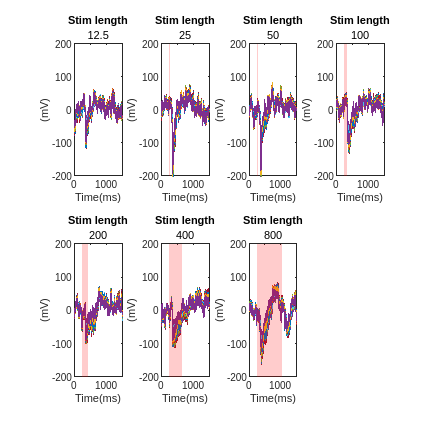

% create the lengths vector
def_stim_lens = [12.5, 25, 50, 100, 200, 400, 800];
stim_inds = 1:140;

% for each stim length, create a mask. take only the relevant segs and
% create a mean and plot it in a subplot. include a backgroud for the stim
% length  in another color.

axes = zeros(length(def_stim_lens));
% plot
figure 
set (gcf, "Position", [100 100 500 500])
for i = 1:length(def_stim_lens)
    % create the current mask.true for i every length of lengths. 
    % for example, for i = 1, the mask will be true for indexs 1,8...
    mask = mod(stim_inds + (length(def_stim_lens)-i), length(def_stim_lens))==0; 
    curr_segs = segs(:,mask,:); % creating a new matrix with only the segs needed.
    curr_mean = squeeze(mean(curr_segs,2)); % create the mean of all the stimulations for each electro. for an stim lengths.

    %ploting
    axes(i) = subplot(2,4,i);
    plot(times,curr_mean); 
    title ('Stim length', num2str(def_stim_lens(i)));
    xlabel('Time(ms)');
    ylabel('(mV)');
    yl = [-200, 200];
    ylim(yl);

    
    %Stimulus shading
    %Define the x-coordinates for the shaded region
    xStart = t_trig_ms;
    xEnd = t_trig_ms + def_stim_lens(i);

    % Define the corresponding y-values for the shaded region
    %yMin = min(curr_mean);
    %yMax = max(curr_mean);
    

    %  Create the polygon vertices for the shaded region
    verticesX = [xStart, xStart, xEnd, xEnd];
   % verticesY = [yMin, yMax, yMax, yMin];
    verticesY = [yl(1), yl(2), yl(2), yl(1) ];
    % Fill the shaded region
    hold on;
    fill(verticesX, verticesY, 'r', 'FaceAlpha', 0.2, 'EdgeColor','none');
    hold off;


end

saveas (gcf, strcat(AnalysisFolder,filesep, 'perStim477.pdf'));

## play

A = 1:10;
A =reshape(A,[1,5,2]);
A(1,2:3,1)

ans =      2     3
